clear all; close all;
SetPathRobotics()

Robotics, Vision & Control: (c) Peter Corke 1992-2011 http://www.petercorke.com
- Robotics Toolbox for Matlab (release 9.10)
 - pHRIWARE (release 1.1): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2022) (c)
** Release <!DOCTYPE HTML PUBLIC "-//IETF//DTD HTML 2.0//EN">
<html><head>
<title>301 Moved Permanently</title>
</head><body>
<h1>Moved Permanently</h1>
<p>The document has moved <a href="https://www.petercorke.com/RTB/currentversion.php">here</a>.</p>
</body></html>
 now available

Run rtbdemo to explore the toolbox
The path for the files used in the couse 4DC00 is set!


%vertices / nodes (each column is a vertice) 
P=[0  0  0  3  3  3 
   0  0  2  2  0  0 
   0  1  0  0  1  0  
   1  1  1  1  1  1]

P =      0     0     0     3     3     3
     0     0     2     2     0     0
     0     1     0     0     1     0
     1     1     1     1     1     1


s = size(P);
Number_vertices = s(2)

Number_vertices = 6

Edge_array=[1 2
            2 3
            3 1
            1 6
            2 5
            3 4
            4 5
            5 6
            6 4]

Edge_array =      1     2
     2     3
     3     1
     1     6
     2     5
     3     4
     4     5
     5     6
     6     4


s = size(Edge_array);
Number_of_edges = s(1)

Number_of_edges = 9

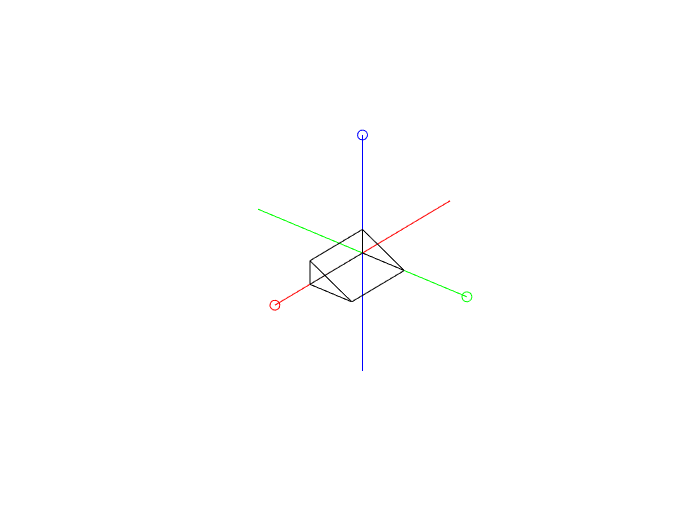


objplot(P,Edge_array,Number_vertices,Number_of_edges);

% change the view point 
view(130,30)

T1 = trotx(pi/2) %creating rotation matrix

T1 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


T1=trotx(pi/2)

T1 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000



P1=T1*P

P1 =          0         0         0    3.0000    3.0000    3.0000
         0   -1.0000    0.0000    0.0000   -1.0000         0
         0    0.0000    2.0000    2.0000    0.0000         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



objplot(P1,Edge_array,Number_vertices,Number_of_edges,'m'); view(130,30)

disp('Prism rotated about the world''s x axis of 90 deg')

Prism rotated about the world's x axis of 90 deg



%*************************************
% Transform 2 w.r.t. xyz OF THE WORLD

T2=transl(-2,0,0)

T2 =      1     0     0    -2
     0     1     0     0
     0     0     1     0
     0     0     0     1



P2=T2*P1

P2 =    -2.0000   -2.0000   -2.0000    1.0000    1.0000    1.0000
         0   -1.0000    0.0000    0.0000   -1.0000         0
         0    0.0000    2.0000    2.0000    0.0000         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



objplot(P2,Edge_array,Number_vertices,Number_of_edges,'c'); view(130,30)

disp('Prism translated about the world''s x axis of -2 units (e.g., meters)')

Prism translated about the world's x axis of -2 units (e.g., meters)




%*************************************
% Transform 3 w.r.t. xyz OF THE WORLD

T3=trotz(pi/2)

T3 =     0.0000   -1.0000         0         0
    1.0000    0.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


P3=T3*P2

P3 =    -0.0000    1.0000   -0.0000   -0.0000    1.0000    0.0000
   -2.0000   -2.0000   -2.0000    1.0000    1.0000    1.0000
         0    0.0000    2.0000    2.0000    0.0000         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


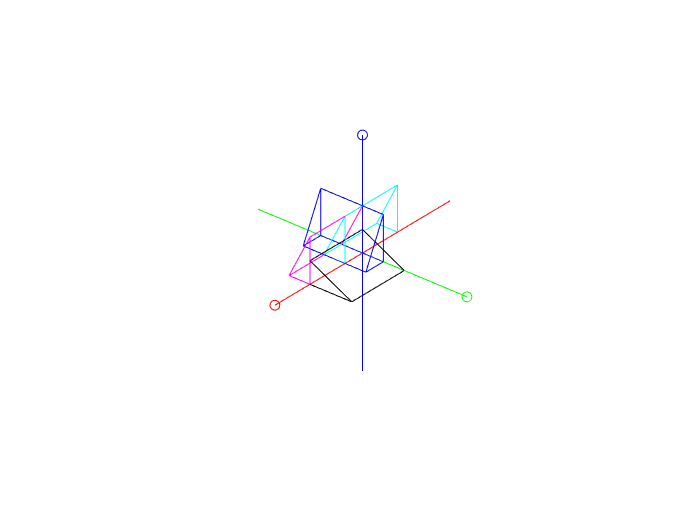

objplot(P3,Edge_array,Number_vertices,Number_of_edges,'b'); view(130,30)


disp('Prism rotated about the world''s z axis of 90 deg')

Prism rotated about the world's z axis of 90 deg
